## Assignment 1 - Scripps Pier Temperature

clear all
close all
load SIO_TEMP_1917_2023_fill.mat

## Figure 1. Plot of SIO Pier temperature, with extreme high  (> 99%) and low (<1%) values indicated

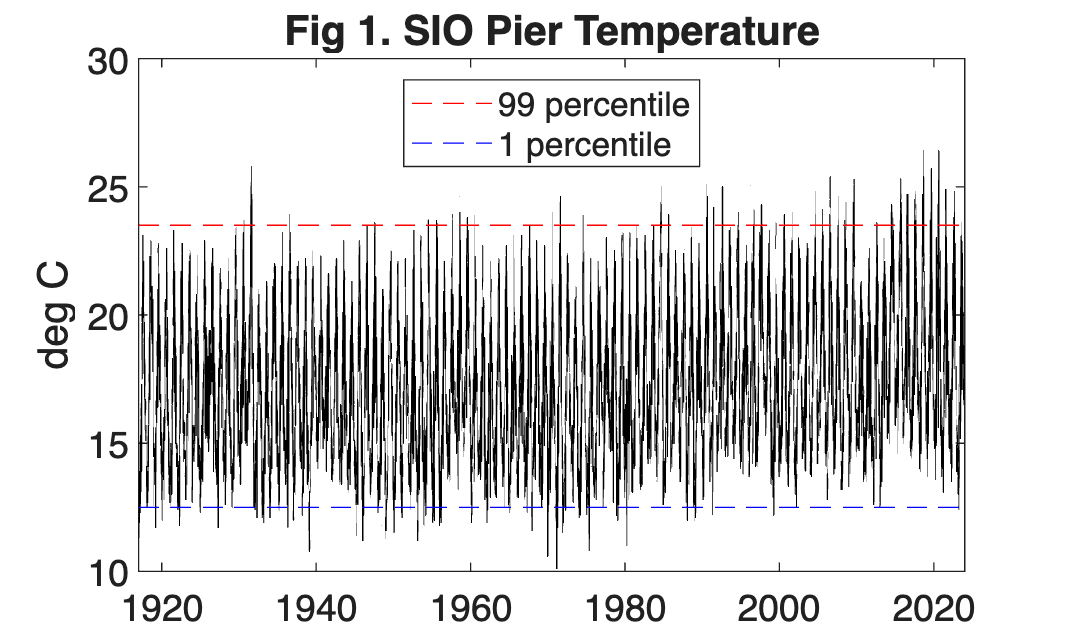

figure (1)
clf
plot(time,T,'k')
hold on
plot([time(1) time(end)],[prctile(T,99) prctile(T,99)],'r--')
plot([time(1) time(end)],[prctile(T,1) prctile(T,1)],'b--')
hold off
ylabel('deg C')
title('Fig 1. SIO Pier Temperature')
legend('','99 percentile','1 percentile','Location','north')
set(gca,'FontSize',14)

## Figure 2. Histogram of year of high values

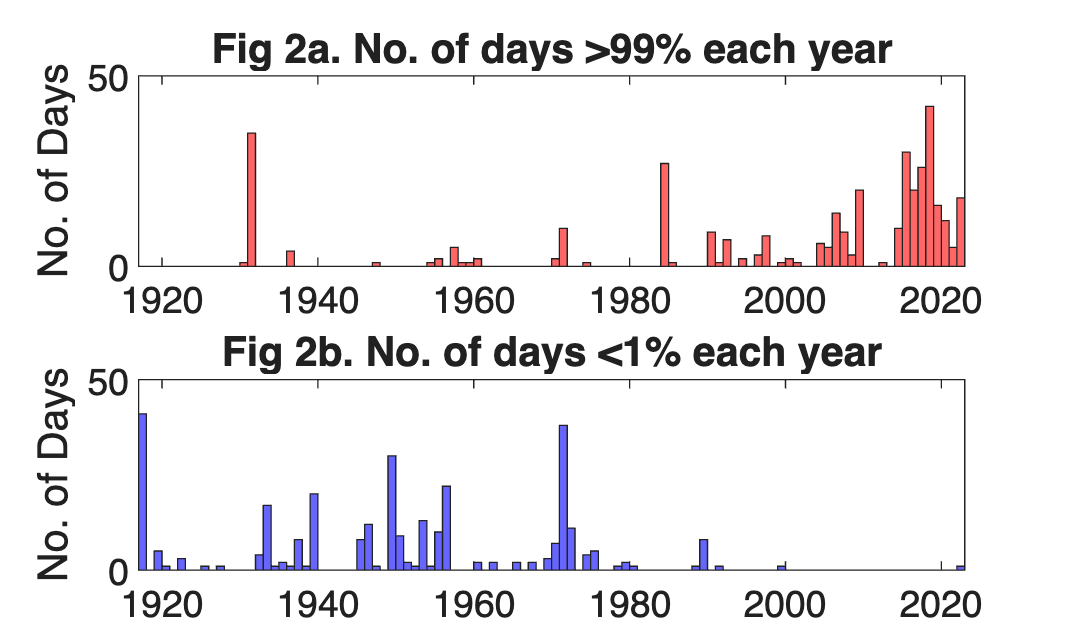

[yr,mo,dy] = datevec(time);

figure (2)
clf
subplot(2,1,1)
histogram(yr(T > prctile(T,99)),'BinWidth',1,'FaceColor', 'r')
ylabel('No. of Days')
title('Fig 2a. No. of days >99% each year')
xlim([1917 2023])
set(gca,'FontSize',14)
subplot(2,1,2)
histogram(yr(T < prctile(T,1)),'BinWidth',1,'FaceColor', 'b')
ylabel('No. of Days')
title('Fig 2b. No. of days <1% each year')
xlim([1917 2023])
set(gca,'FontSize',14)

## Figure 3. Histogram of month of high values

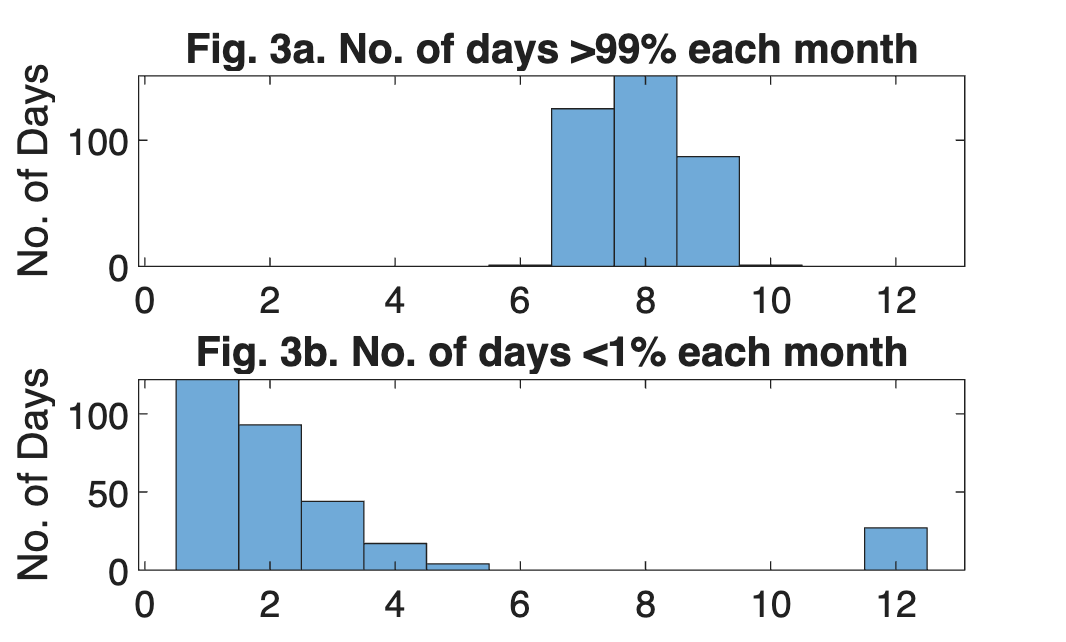

figure (3)
clf
subplot(2,1,1)
histogram(mo(T > prctile(T,99)),[0.5:12.5])
ylabel('No. of Days')
title('Fig. 3a. No. of days >99% each month')
set(gca,'FontSize',14)
subplot(2,1,2)
histogram(mo(T < prctile(T,1)),[0.5:12.5]);
ylabel('No. of Days')
title('Fig. 3b. No. of days <1% each month')
set(gca,'FontSize',14)

## Figure 4. Histograms of JAS summer temperature during first 30 and last 30 years

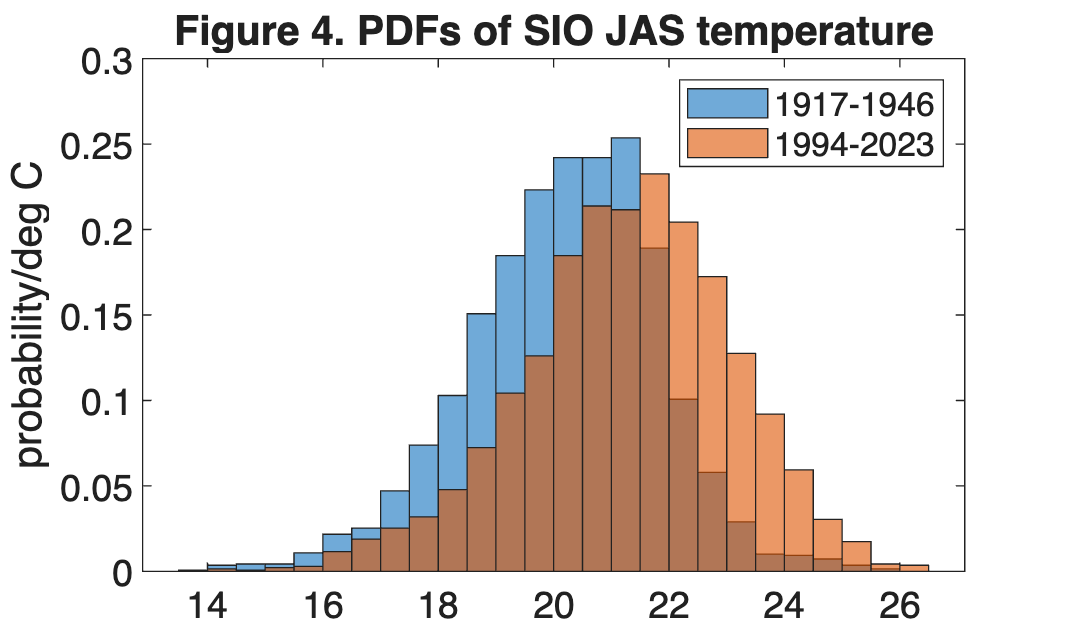

T_summer = T(mo>=7 & mo <=9);
uyr = unique(yr);
nyr = length(uyr);
nday = 31+31+30;
T_summer = reshape(T_summer,nday,nyr);
time_summer = time(mo>=7 & mo <=9);
time_summer = reshape(time_summer,nday,nyr);

figure (4)
clf
histogram(T_summer(:,uyr < uyr(1)+30),'normalization','pdf')
hold on
histogram(T_summer(:,uyr > uyr(end)-30),'normalization','pdf')
legend('1917-1946','1994-2023')
ylabel('probability/deg C')
title('Figure 4. PDFs of SIO JAS temperature')
set(gca,'FontSize',14)
hold off

## 5. JAS summer temperatures during 2022, with 5th, 50th, and 95th percentiles

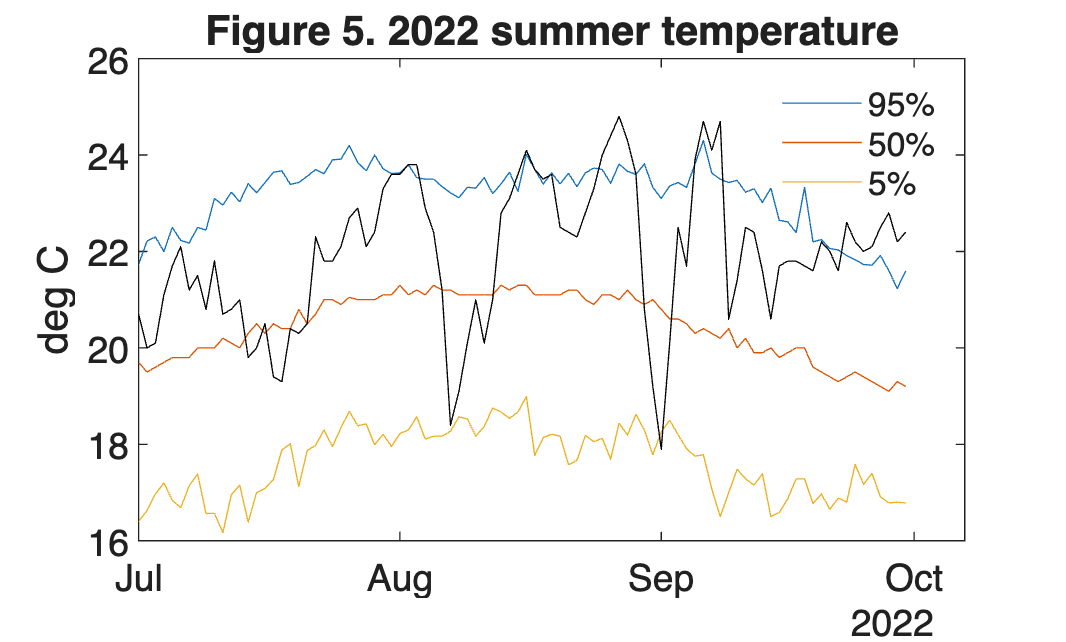

heat_year = 2022;
figure (5)
clf
plot(time_summer(:,uyr==heat_year),prctile(T_summer,[95 50 5],2))
ylabel('deg C')
hold on
plot(time_summer(:,uyr==heat_year),T_summer(:,uyr==heat_year),'k')
hold off
legend('95%','50%','5%')
legend('boxoff')
title(['Figure 5. ',int2str(heat_year),' summer temperature'])
set(gca,'FontSize',14)

## Figure 6. Number of JAS days above the 95th percentile

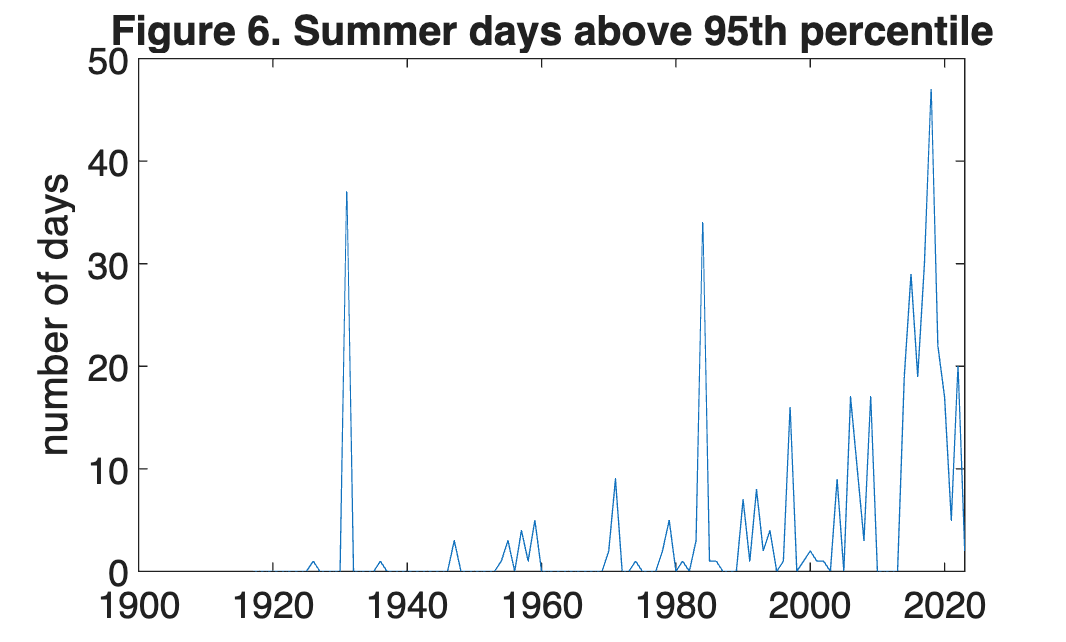

figure (6)
clf
T_95 = prctile(T_summer,95,2);
for j = 1:nyr
    MHW(j) = sum(T_summer(:,j) > T_95);
end
plot(uyr,MHW)
ylabel('number of days')
title('Figure 6. Summer days above 95th percentile')
set(gca,'FontSize',14)

## Figure 7. Time series plot of mean JAS temperature and heat wave days

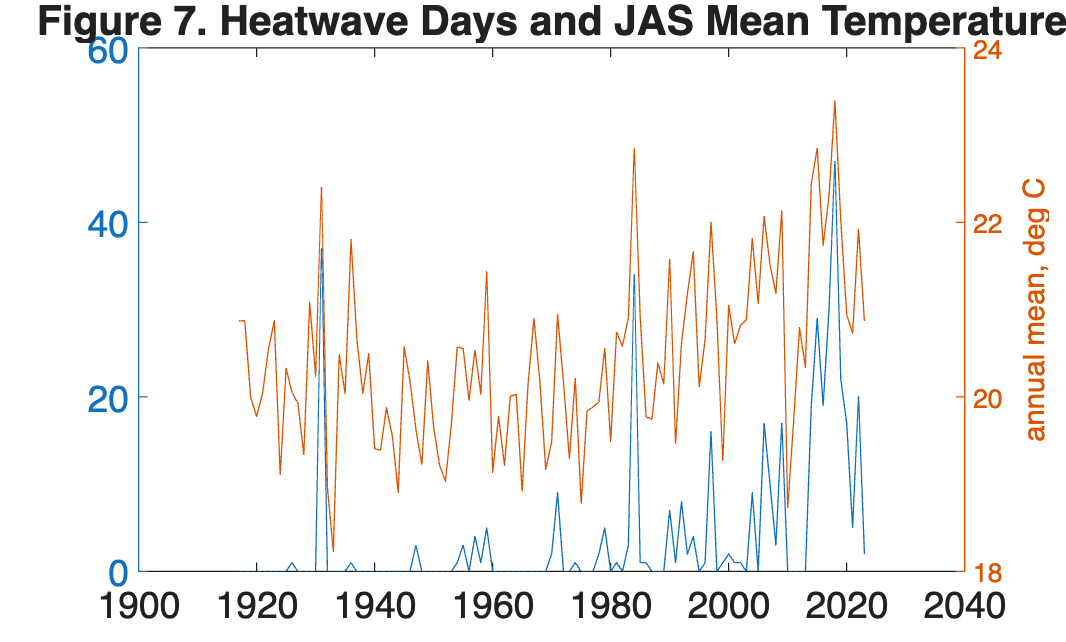

T_summer_mean = mean(T_summer);

figure (7)
clf
[hAx,hLine1,hLine2] = plotyy(uyr,MHW,uyr,T_summer_mean);
ylabel(hAx(2),'annual mean, deg C') % right y-axis
title('Figure 7. Heatwave Days and JAS Mean Temperature')
set(gca,'FontSize',14)

## Figure 8. Scatter plot of mean JAS temperature vs heat wave days

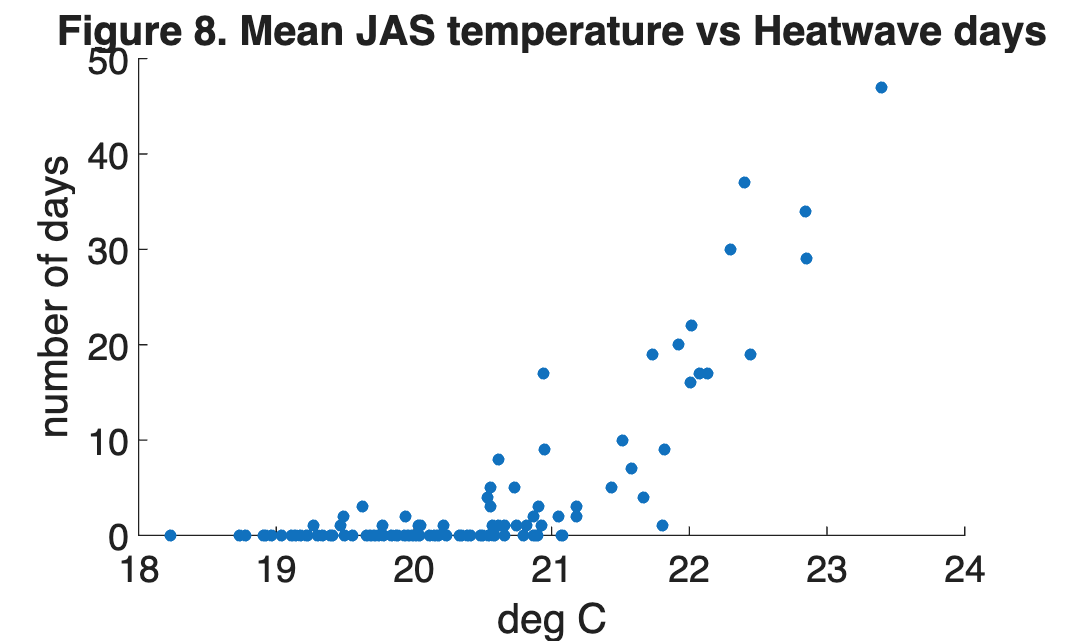


figure (8)
clf
scatter(T_summer_mean,MHW,20,'filled')
xlabel('deg C')
ylabel('number of days')
title('Figure 8. Mean JAS temperature vs Heatwave days')
set(gca,'FontSize',14)